# Check Energy Spectra

## Input h5 Files

clear all;
fileNameStr = 'C:\Users\nithin\Downloads\20080326.001_bc_15se-energyFlux.h5';
fileNameStr0 = 'G:\My Drive\Research\Projects\Paper 2\Data\Event 1\20080326.001_bc_15sec-fitcal.h5';

## Loading data

data.energyFlux = permute(h5read(fileNameStr,'/energyFluxFromMaxEnt/energyFlux'),[3 2 1]); % in [m^-3]

Error using h5readc
The filename specified was either not found on the MATLAB path or it contains unsupported characters.

Error in h5read (line 58)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

data.qInput = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInput'); % Need to fix this order
data.qInverted = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInverted');% Need to fix these
data.time = h5read(fileNameStr,'/energyFluxFromMaxEnt/time')';
data.electronDensity = permute(h5read(fileNameStr,'/inputData/Ne'),[3 2 1]);
data.energyBin = h5read(fileNameStr,'/energyFluxFromMaxEnt/energyBin')';
data.alt = h5read(fileNameStr,'/energyFluxFromMaxEnt/alt')';

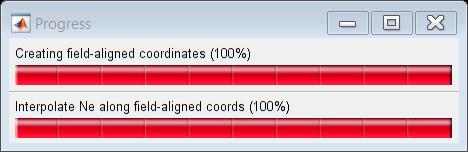

amisr = read_amisr(fileNameStr0);
data.magBeamNo = amisr.magBeamNo;
amisrData= aer_to_field_aligned_coords(amisr,70);

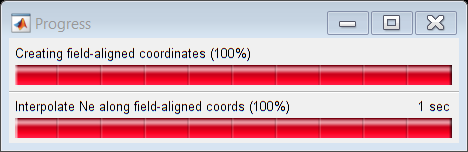

timeMinStr = '26 Mar 2008 08:00:00';
timeMaxStr = '26 Mar 2008 13:00:00';
amisrData = interpolate_to_field_aligned_coords(amisrData,timeMinStr,timeMaxStr);

% clearvars amisr

avg.MSE = 0.78155 avg.iterno = 2316.2275
avg.MSE = 0.27454 avg.iterno = 9402.3751
avg.MSE = 0.33905 avg.iterno = 7447.9614
avg.MSE = 0.24071 avg.iterno = 8352.2936
avg.MSE = 0.42566 avg.iterno = 1889.5665
avg.MSE = 0.24425 avg.iterno = 11157.1373
avg.MSE = 0.27271 avg.iterno = 10798.0918
avg.MSE = 0.29477 avg.iterno = 5552.0232
avg.MSE = 0.29614 avg.iterno = 5189.267
avg.MSE = 0.36035 avg.iterno = 4520.7442
avg.MSE = 0.30439 avg.iterno = 8836.9897
avg.MSE = 0.27758 avg.iterno = 8097.612
avg.MSE = 0.52579 avg.iterno = 4400.5682
avg.MSE = 0.19901 avg.iterno = 10494.7064
avg.MSE = 0.17646 avg.iterno = 10755.291
avg.MSE = 0.20316 avg.iterno = 10948.6807
avg.MSE = 0.20175 avg.iterno = 8939.224
avg.MSE = 0.31066 avg.iterno = 7767.1013
avg.MSE = 0.19455 avg.iterno = 13201.6369
avg.MSE = 0.37857 avg.iterno = 4494.5133
avg.MSE = 0.21436 avg.iterno = 6753.6961
avg.MSE = 0.24129 avg.iterno = 5804.297
avg.MSE = 0.20386 avg.iterno = 6324.9408
avg.MSE = 0.24937 avg.iterno = 6935.7674
avg.MSE = 0.297

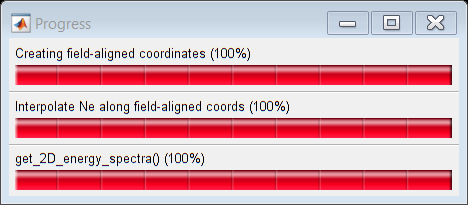

altLim = [60 200];
energyBin = logspace(3,6,30);
amisrData.time = (crop_time(amisrData.time',amisrData.time(1,:),timeMinStr,timeMaxStr))';
[dataInv, magcoords, dataInputInv] = get_2D_energy_spectra(amisrData, energyBin',timeMinStr,timeMaxStr,altLim,'magnetic');

## Plotting

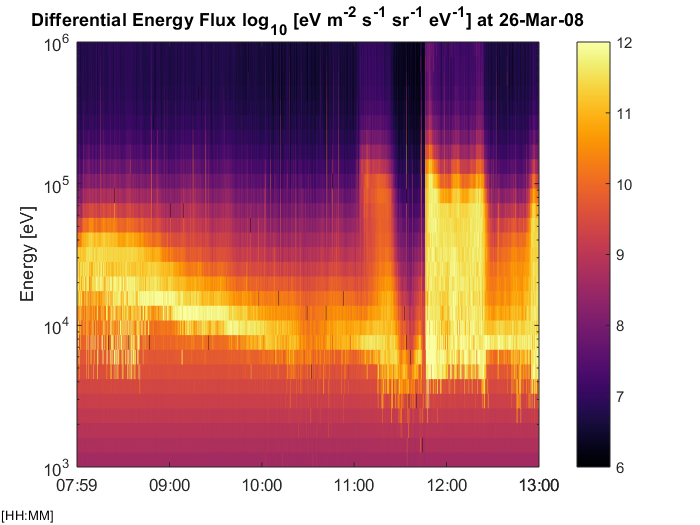

% Time

figure;
% z = squeeze(data.energyFlux(:,data.magBeamNo,:));
z = squeeze(mean(data.energyFlux,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.energyBin',log10(z)',1,3,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

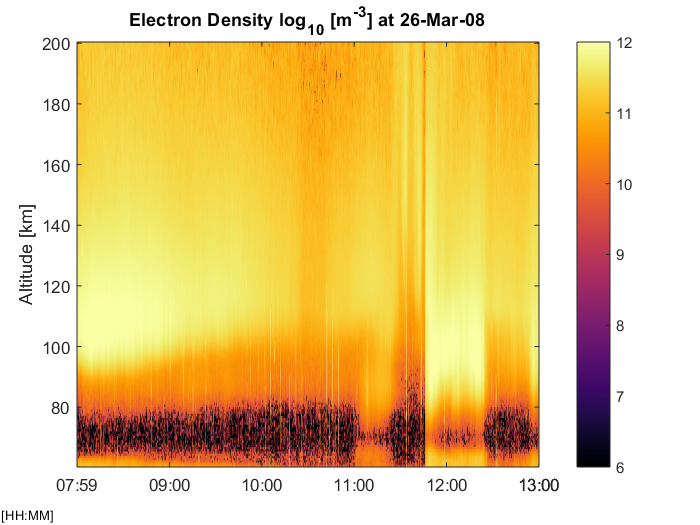

figure;
z = squeeze(mean(data.electronDensity,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.alt',log10(z)',1,1,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

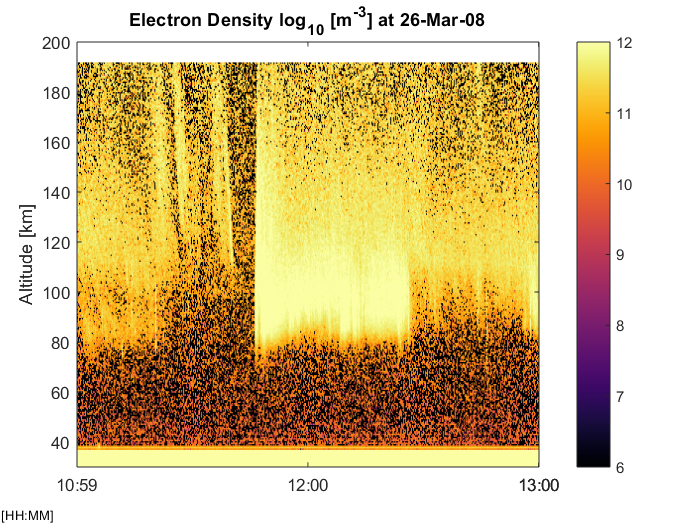

figure;
iBeam = 4;
z = squeeze((permute(amisr.electronDensity(:,iBeam,:),[3 2 1])));
z(z<=0)=10^3;
plot_2D_time_series(amisr.time(1,:)',amisr.altitude(:,iBeam)',log10(z)',1,1,timeMinStr,timeMaxStr);
colormap('inferno');
ylim([30 200]);
caxis([6 12]);
colorbar;

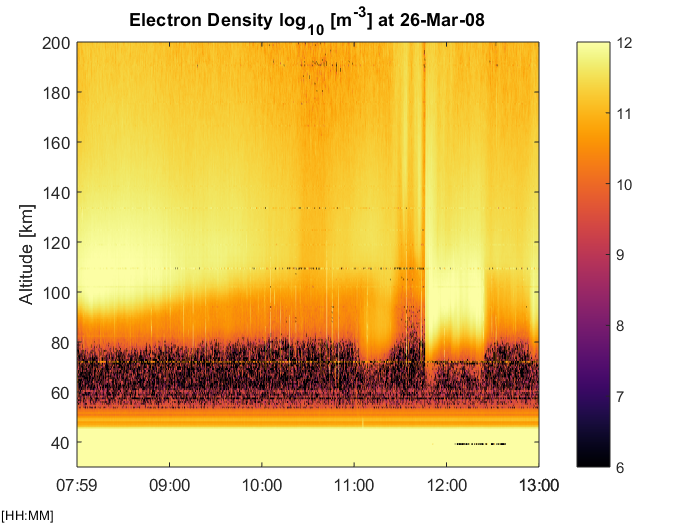


figure;
iBeam = 4;
z = squeeze(nanmean(permute(amisrData.magElectronDensity,[3 2 1]),2));
% z = squeeze((permute(amisrData.magElectronDensity(:,iBeam,2555:end),[3 2 1])));
z(z<=0)=10^3;
% time = crop_time(amisrData.time(1,:),amisrData.time(1,:),timeMinStr,timeMaxStr);
plot_2D_time_series(amisrData.time(1,:)',amisrData.magCartCoords.zUp(:,iBeam)',log10(z)',1,1);
colormap('inferno');
ylim([30 200]);
caxis([6 12]);
colorbar;

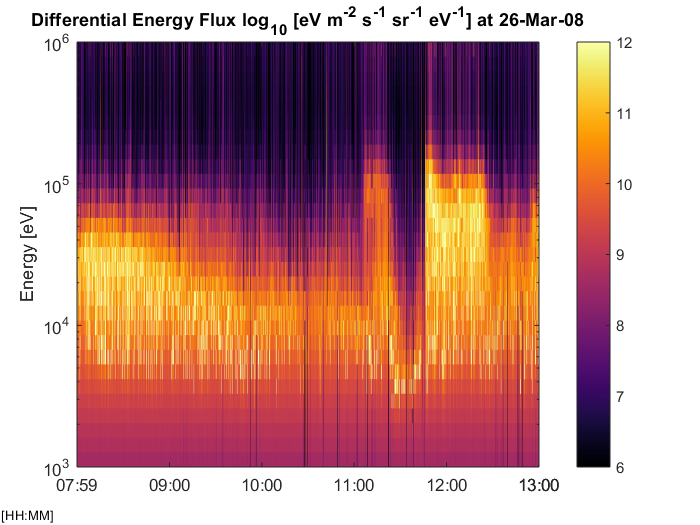

figure;
% z = zeros(size(dataInv(1).energyFlux));
% for i = 1:26
%     iBeam=i;
%     z = z + (dataInv(iBeam).energyFlux);
% end
% z=z/26;
iBeam = 3;
z = squeeze(dataInv(iBeam).energyFlux);
z(z<=0)=10^1;
plot_2D_time_series(dataInv(iBeam).time,dataInv(iBeam).energyBin,log10(z),1,3,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

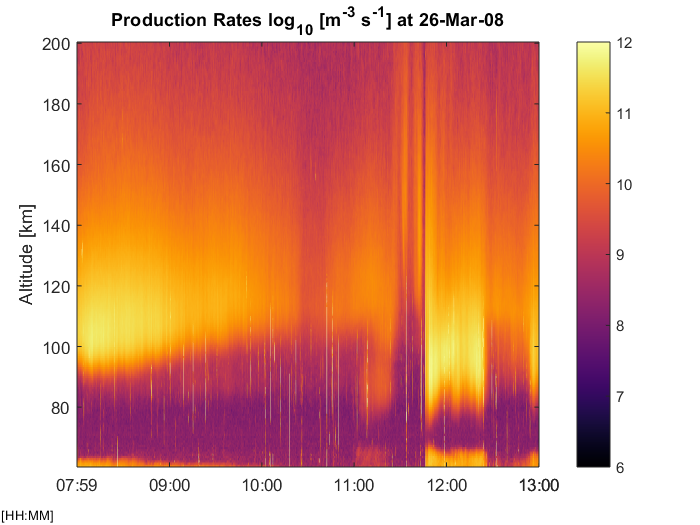


figure;
z = squeeze(mean(data.qInput,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.alt',log10(z)',1,2,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;

## Investigating the neflection

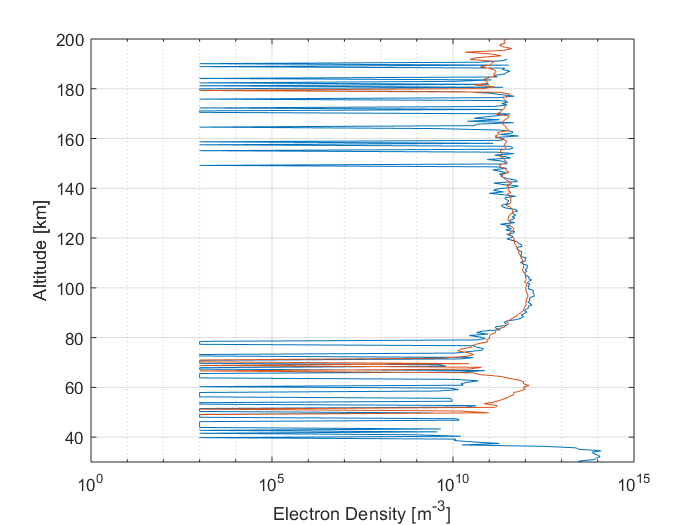


figure; 
iBeam = 4;
z = squeeze((permute(amisr.electronDensity(:,iBeam,:),[3 2 1])));
z(z<=0)=10^3;
plot_1D_time_slice(amisr.time(1,:)',amisr.altitude(:,iBeam)',z','26 Mar 2008 12:00',1);
ylim([60 200]);
hold on;
z1 = squeeze((permute(amisrData.magElectronDensity(:,iBeam,:),[3 2 1])));
z1(z1<=0)=10^3;
plot_1D_time_slice(amisrData.time(1,:)',amisrData.magCartCoords.zUp(:,iBeam)',z1','26 Mar 2008 12:00',1);
ylim([30 200]);